Condiçao 1: -1 < K < 1

Condiçao 2: K > - 0.5

Condiçao 3: K > -1.5


K = 0.2 | Jury: 1 1 1


Polos e modulos:
   0.2500 + 0.3708i   0.4472 + 0.0000i
   0.2500 - 0.3708i   0.4472 + 0.0000i




K = 1.0 | Jury: 0 1 1


Polos e modulos:
   0.2500 + 0.9682i   1.0000 + 0.0000i
   0.2500 - 0.9682i   1.0000 + 0.0000i




K = 1.2 | Jury: 0 1 1


Polos e modulos:
   0.2500 + 1.0665i   1.0954 + 0.0000i
   0.2500 - 1.0665i   1.0954 + 0.0000i



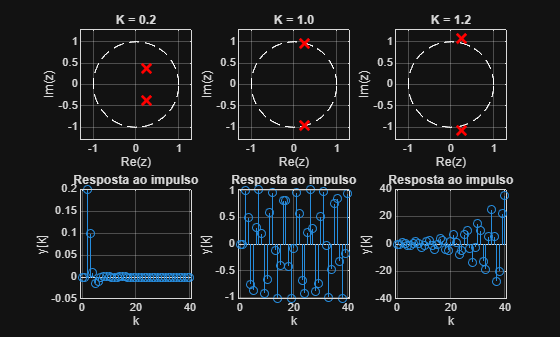

% Segunda ordem: T(z) = K/(z^2 - 0.5*z + K)
    ganhos = [0.2 1 1.2];
    k = 0:40;
    u = [1 zeros(1,length(k)-1)];                
    theta = linspace(0,2*pi,500);
    
    % Repetiçao para os três casos
    for i = 1:length(ganhos)
    
        % Entrada de dados
        K = ganhos(i);
        a = [1 -0.5 K];
    
        % Condições de Jury 
        testes = [abs(a(3))<a(1), polyval(a,1)>0, polyval(a,-1)>0];
    
        
        p = roots(a);
        y = filter([0 0 K],a,u);      
        fprintf('\nK = %.1f | Jury: %d %d %d\n',K,testes);
        disp('Polos e modulos:'); disp([p abs(p)]);
    
    
        % Plotagem dos polos e resposta temporal (em número de amostras)
        subplot(2,3,i);
        plot(cos(theta),sin(theta),'w--'); hold on; % Círculo unitário
        plot(real(p),imag(p),'rx','MarkerSize',10,'LineWidth',2);
        axis equal; axis([-1.3 1.3 -1.3 1.3]); grid on;
        title(sprintf('K = %.1f',K)); xlabel('Re(z)'); ylabel('Im(z)');
    
        subplot(2,3,i+3);
        stem(k,y); grid on;
        xlabel('k'); ylabel('y[k]'); title('Resposta ao impulso');
    end

% Terceira ordem: linha b da tabela de Jury
P = [1 -1.5 0.66 -0.08];
b = P(4)*P(2:4) - P(1)*P(3:-1:1);
testes = [abs(P(4))<P(1), polyval(P,1)>0, polyval(P,-1)<0, abs(b(3))>abs(b(1))];
disp('Terceira ordem: [b0 b1 b2]'); disp(b);

Terceira ordem: [b0 b1 b2]
   -0.5400    1.4472   -0.9936



disp('Jury: 1 = condicao atendida, 0 = nao atendida'); disp(testes);

Jury: 1 = condicao atendida, 0 = nao atendida
   1   1   1   1



disp('Polos do exemplo de terceira ordem:'); disp(roots(P));

Polos do exemplo de terceira ordem:
    0.8000
    0.5000
    0.2000

